# Direct Path and Bistatic SNR Analysis

## Summary of Analysis and Workflow

This script performs a comprehensive **signal-to-noise ratio (SNR) analysis** for both **direct-path** and **bistatic radar configurations. **FM/ HDTV broadcast towers are as illuminators of opportunity. The first phases of the analysis use FM data to perform the initial direct path analysis and tower identification.  The bistatic analysis is performed using the candidate towers and the HDTV-specific parameters. The objective is to evaluate radar coverage and detection performance over a defined region, incorporating terrain effects and realistic system parameters.

**Analysis Goals**

- Estimate received signal strength and SNR for direct-path links between FM towers and a fixed receiver at MathWorks' Apple Hill Campus. Visualize coverage and identify the most effective transmit towers for detection.

- Compute bistatic SNR for HDTV signals for targets within a commercial flight path, considering propagation losses and radar equation parameters as a preliminary confirmation of sufficient SNR for target detection.

**Workflow Overview**

- **Data Acquisition and Site Setup**

- Load FM station data and parse tower information (location, antenna height, transmit power, gain) from input files.

- Match tower coordinates to FCC records to retrieve carrier frequencies.

- Create radar transmitter sites and a receiver site at a fixed location.

- **Direct-Path Analysis**

- Compute received signal strength from selected towers using MATLAB propagation tools.

- Calculate thermal noise power based on Boltzmann’s constant, reference temperature, bandwidth, and receiver noise figure.

- Convert SNR from dB to linear scale and estimate available received power.

- **Bistatic Coverage Analysis**

- Define a region of interest (ROI) and generate a grid of target positions at specified altitude.

- Apply terrain-aware propagation models (TIREM or Longley-Rice) to compute path loss and distances between transmitters, receiver, and targets.

- Use the bistatic radar equation to calculate SNR for each target-transmitter pair, accounting for wavelength, transmit power, integration time, radar cross section (RCS), and terrain losses.

- **Visualization and Performance Assessment**

- Identify the tower with the highest average SNR across the field of view.

- Generate an SNR contour map over the ROI and display radar coverage using geospatial visualization tools.

- Highlight selected towers (e.g., Newton and Hudson) for focused bistatic SNR analysis.

- **Helper Functions**

- Includes utilities for parsing tower data, matching stations to FCC records, generating target trajectories, and computing zoom levels for map visualization.

## Set Up Radar Sites

%viewer = siteviewer("Terrain","gmted2010");
% Import FM Station List Table - Contains Frequency Info
load('FM_stationList.mat');

% Parse the Radio_Tower_List.txt file:
filename = "Radio_Tower_List.txt";
[rdrlats, rdrlons,rdrcoverage,rdrheights,rdrtxpowers,gains] = parseTxtRadarLocs(filename);
carrierFreqTable = matchStationsToFCC(filename, FM_stationList);
% Currently using AGL as antenna height, but could use the "station
% details" value that is a different height for "worst case" analysis

%rdrlats = [41.993402, 41.829362, 41.670084];
%rdrlons = [-70.067451, -69.996564, -69.952308];
names = "Radar site" + (1:length(rdrlats));

To add an antenna/array to the TX/RX sites use the "Antenna" property as in this example: https://www.mathworks.com/help/antenna/ug/planning-a-5G-fixed-wireless-access-link-over-terrain.html#PlanningA5GFixedWirelessAccessLinkOverTerrainExample-4

% Create transmitter sites associated with radars
for i=1:numel(names)
    rdrtxs(i) = txsite("Name",names(i), ...
        "AntennaHeight",rdrheights(i), ...
        "Latitude",rdrlats(i), ...
        "Longitude",rdrlons(i),...
        "TransmitterPower",rdrtxpowers(i));
end

% Create receiver site at MathWorks
MWLoc = [42.299293, -71.349500];
MWName = "MW Antenna site";

rdrrxs = rxsite("Name",MWName, ...
    "AntennaHeight",25, ...
    "Latitude",MWLoc(1), ...
    "Longitude",MWLoc(2));

% Show just the radar transmitter sites
show(rdrtxs);

## Simplest Case - View LOS

los(rdrrxs,rdrtxs)

## Higher Fidelity, incorporates the transmit power from the towers

rtpm = propagationModel("raytracing", ...
    Method="sbr", ...
    MaxNumReflections=0, ...
    TerrainMaterial="PEC");
rayOut = raytrace(rdrtxs,rdrrxs,rtpm);


## Calculate the Input Power for the antennas of interest - Hudson and Newton

Direct Path

NewtonTX = rdrtxs(5);
HudsonTx = rdrtxs(end);
ss_Newton_dBm = sigstrength(rdrrxs,NewtonTX)

ss_Newton_dBm = -28.8871

ss_Hudson_dBm = sigstrength(rdrrxs,HudsonTx)

ss_Hudson_dBm = -39.8370

## Calculate Target Path

% Ps / Pn = SNR - by definition
% Ps = SNR*Pn
% Pn = k (F−1) TRef*BW
% TRef - 290K
% FdB=10log10(F) - where Fdb is noise Figure and "F" is noise Factor - needed above
% F = 10^(FdB/20)
F = 10^(2.5/10);
TRef = 290;
k = physconst('Boltzmann');
Pn = k*(F-1)*TRef*6e6; % Using HDTV Bandwidth

% Calculate the Available Receive Power according to the SNR values from
% above
% From Below - NewtonMeanSNR = 57.78dB, HudsonMeanSNR = 69.91
SNR_dB_FOV = 69.91;
SNR_linear = 10^(SNR_dB_FOV/10);
Ps = SNR_linear*Pn; % W
Ps_dBm = 10*log10(Ps)

Ps_dBm = -67.3723


% Which Should You Use? Note from Copilot
% MW phased uses F-1: This is because they model the additional noise introduced by the receiver beyond 
% the thermal noise at the reference temperature. The term (F−1)TRef(F - 1) T_{\text{Ref}}(F−1)TRef� represents the excess noise temperature due to the receiver.
% 
% For link budget and absolute signal power estimation, use total noise:
% Pn=k⋅F⋅TRef⋅BWP_n = k \cdot F \cdot T_{\text{Ref}} \cdot BWPn�=k⋅F⋅TRef�⋅BW
% 
% For toolbox consistency (e.g., phased array simulations), use:
% Pn=k⋅(F−1)⋅TRef⋅BWP_n = k \cdot (F - 1) \cdot T_{\text{Ref}} \cdot BWPn�=k⋅(F−1)⋅TRef�⋅BW


## **Bistatic Analysis**

### Lay Down Region of Interest - Requires User Input

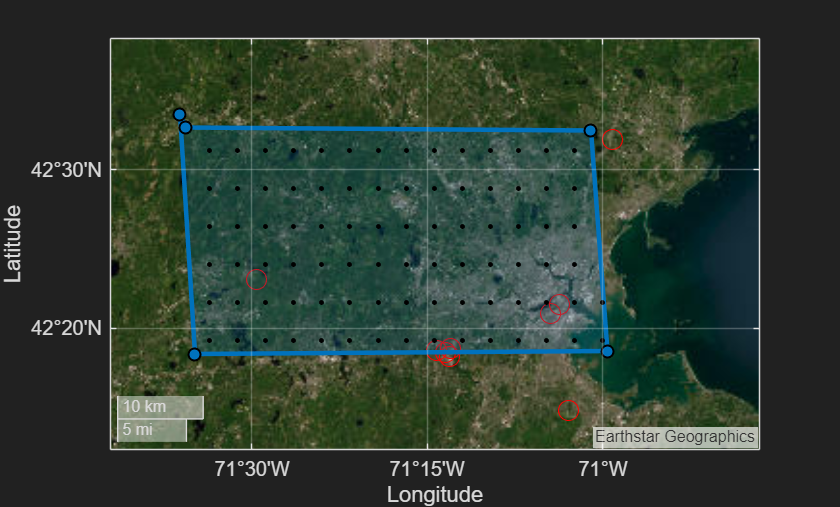

% Geoaxes plot provides satellite view
missionView = geoaxes('Basemap','satellite');
hold(missionView,"on")

% Plot radar locations
geoplot(missionView, rdrlats, rdrlons, 'LineStyle','none','Marker','o', 'MarkerSize', 10, 'Color', 'r');

% Center us over Massachusetts Bay and put us at 60 km above the ground
lla0 = [mean(rdrlats), mean(rdrlons) 0];
%llao = [ ]
missionView.MapCenter = lla0(1:2);
zoomLevel = heightToZoomLevel(60000, 42.354890608305496);
missionView.ZoomLevel = zoomLevel;

% Draw region of interest for coverage
ROI = drawpolygon(missionView); 
%ROI = drawpolyline(missionView); 
ROI.Tag = "Radar Coverage ROI"; 
RadarCoveragePolyshape = polyshape(ROI.Position);

delta = 0.04; % Target spacing in latitude and longitude (degrees) -- effectively our coverage resolution here.
% Target spacing above ground level (meters) -- resolution in altitude of coverage plot.
altinMeters = convlength(6e3,'ft','m');
tgtHgtsAGL = altinMeters;% :1e3:8e3; % Need to change helper to incorporate multiple target heights
[tgtLLA,hTgts] = helperRadarCoverageTargetGrid(RadarCoveragePolyshape,delta,tgtHgtsAGL,missionView);

## **Calculate SNR for Target Positions with Terrain**

% Create a terrain propagation model, using TIREM or Longley-Rice
tiremloc = tiremSetup;
if ~isempty(tiremloc)
    pm = propagationModel("tirem");
else
    pm = propagationModel("longley-rice");
end
tgtlats = tgtLLA(1,:);
tgtlons = tgtLLA(2,:);
tgtalt = tgtLLA(3,:);

% Compute additional path loss due to terrain and return distances between radars and targets 
[L,dsRecTgt,dsTransTgt] = helperPathlossOverTerrain(pm,rdrtxs,rdrrxs,tgtlats,tgtlons,tgtalt);
%bistaticDistances = [dsRecTgt dsTransTgt];

Use the radar equation to compute the SNR at each radar receiver for the signal reflected from each target.

% Compute SNR for all radars and targets
numtgts = numel(tgtlats);
numrdrs = numel(rdrtxs);
rawsnr = zeros(numtgts,numrdrs);

% For bistatic:
%Bistatic radar - the transmitter and receiver are separated. 
% tgtrng is a 1-by-2 row vector with real-valued positive elements or a 
% J-by-2 matrix with real-valued positive elements. J is the number of targets. 
% Each row of tgtrng has the form [TxRng RxRng], where TxRng is the range from 
% the transmitter to the target and RxRng is the range from the receiver to the target.

%% Should be factored into ERP - don't use this NV pair for our data
% rxGain = ones(size(gains));
% antgain = [gains rxGain]; 

c = physconst("LightSpeed");
%tau = 1e-3; % Assuming CW for FM broadcast, so tau should match radar's integration
tau = 1/(200e3); 
%tgtrcs = 5; % (m^2) for proplane (monostatic)
tgtrcs = 0.5; % (m^2) for proplane (bistatic - "worse case", maybe could be worse)

for tgtind = 1:numtgts
    for rdrind = 1:numrdrs
        fc = carrierFreqTable.CarrierFrequency_Hz(rdrind);
        lambda = c/fc;
        rawsnr(tgtind,rdrind) = radareqsnr(lambda,[dsRecTgt(tgtind), dsTransTgt(tgtind,rdrind)], rdrtxpowers(rdrind), tau,...  %ds(tgtind,rdrind)
            RCS=tgtrcs,Loss=L(tgtind,rdrind));  %Gain=antgain
    end
end

## **Find which transmit tower corresponds to maximum average SNR for FOV**

This was used to identify the best transmit toweres initially

meanSNRperTower = mean(rawsnr);
% Omit towers that were given placeholder carrier Frequencies
meanSNRperTower = meanSNRperTower(carrierFreqTable.IsWithinThreshold);
[bestSNR,towerID] = max(meanSNRperTower);

## HDTV-Specific Bistatic SNR Analysis for Newton and Hudson

%% HDTV-Specific Bistatic SNR Analysis for Newton and Hudson
% This section computes bistatic SNR for targets using HDTV parameters
% for Newton (CBS Tower) and Hudson (Univision Tower).

disp('Starting HDTV-specific bistatic SNR analysis for Newton and Hudson...');

Starting HDTV-specific bistatic SNR analysis for Newton and Hudson...



% Physical constants
c = physconst("LightSpeed");
k = physconst('Boltzmann');
TRef = 290; % Reference temperature in Kelvin
FdB = 2.5;  % Noise figure in dB (based on antenna)
F = 10^(FdB/10); % Noise factor

% HDTV parameters
BW = 6e6; % ATSC channel bandwidth (Hz)
tau = 1/(200e3); % Integration time (same as FM analysis)
tgtrcs = 0.5; % Target RCS (m^2) for bistatic "worst case"

% ERP placeholders for Newton and Hudson (update if actual values available)
ERP_Newton = 500e3; % W
ERP_Hudson = 500e3; % W

% Carrier frequencies for HDTV
fcNewton = 596.3e6; % Hz
fcHudson = 548e6;   % Hz

% Compute noise power
Pn = k * (F - 1) * TRef * BW; % W

% Convert to dBm for sanity check
Pn_dBm = 10*log10(Pn/1e-3);

% Typical thermal noise reference for comparison
thermalNoiseRef_dBm = -174 + 10*log10(BW); % dBm for 6 MHz bandwidth
thermalNoiseWithNF_dBm = thermalNoiseRef_dBm + FdB;

disp(['Noise power (Pn): ', num2str(Pn), ' W']);

Noise power (Pn): 1.8697e-14 W


disp(['Noise power in dBm (Pn_dBm): ', num2str(Pn_dBm), ' dBm']);

Noise power in dBm (Pn_dBm): -107.2823 dBm


disp(['thermalNoiseRef_dBm for 6MHz: ', num2str(thermalNoiseRef_dBm), ' W']);

thermalNoiseRef_dBm: -106.2185 W


disp(['thermalNoiseWithNF_dBm for 6MHz Adjusted for Noise Figure: ', num2str(thermalNoiseWithNF_dBm), ' W']);

thermalNoiseWithNF_dBm: -103.7185 W



% Prepare arrays for SNR
numtgts = numel(tgtlats);
snrNewtonHDTV = zeros(numtgts,1);
snrHudsonHDTV = zeros(numtgts,1);

% Compute SNR for Newton and Hudson towers
lambdaNewton = c / fcNewton;
lambdaHudson = c / fcHudson;

for tgtind = 1:numtgts
    % Newton tower SNR
    snrNewtonHDTV(tgtind) = radareqsnr(lambdaNewton, ...
        [dsRecTgt(tgtind), dsTransTgt(tgtind, idxNewton)], ...
        ERP_Newton, tau, RCS=tgtrcs, Loss=L(tgtind, idxNewton));
    
    % Hudson tower SNR
    snrHudsonHDTV(tgtind) = radareqsnr(lambdaHudson, ...
        [dsRecTgt(tgtind), dsTransTgt(tgtind, idxHudson)], ...
        ERP_Hudson, tau, RCS=tgtrcs, Loss=L(tgtind, idxHudson));
end

% Convert SNR to dB for visualization
snrNewtonHDTV_dB = 10*log10(snrNewtonHDTV);
snrHudsonHDTV_dB = 10*log10(snrHudsonHDTV);
snrCombinedHDTV_dB = max([snrNewtonHDTV_dB snrHudsonHDTV_dB], [], 2);

%% Visualization using Site Viewer
% Newton Coverage
viewerNewtonHDTV = siteviewer("Name","Newton HDTV Coverage","Basemap","satellite");
rdrDataNewtonHDTV = propagationData(tgtlats, tgtlons, "SNR", snrNewtonHDTV_dB);
contour(rdrDataNewtonHDTV, LegendTitle="Newton HDTV SNR (dB)");
title("Bistatic SNR Coverage - Newton HDTV");

% Hudson Coverage
viewerHudsonHDTV = siteviewer("Name","Hudson HDTV Coverage","Basemap","satellite");
rdrDataHudsonHDTV = propagationData(tgtlats, tgtlons, "SNR", snrHudsonHDTV_dB);
contour(rdrDataHudsonHDTV, LegendTitle="Hudson HDTV SNR (dB)");
title("Bistatic SNR Coverage - Hudson HDTV");

% Combined Coverage
viewerCombinedHDTV = siteviewer("Name","Combined HDTV Coverage","Basemap","satellite");
rdrDataCombinedHDTV = propagationData(tgtlats, tgtlons, "SNR", snrCombinedHDTV_dB);
contour(rdrDataCombinedHDTV, LegendTitle="Max HDTV SNR (Newton or Hudson)");
title("Combined Bistatic SNR Coverage - HDTV");

## Helper Functions

function platStruct = radarPlat2Struct(radarPlats)
    platStructTemplate.Position = [0, 0, 0];
    platStructTemplate.PlatformID = 0;
    platStructTemplate.Dimensions.Length = 0;
    platStructTemplate.Dimensions.Width = 0;
    platStructTemplate.Dimensions.Height = 0;
    platStructTemplate.Dimensions.OriginaOffset = [0, 0, 0];
    platStructTemplate.Orientation = [0, 0, 0];

    platStruct = repmat(platStructTemplate, [1, length(radarPlats)]);

    for ii = 1:length(radarPlats)
        platStruct(ii).Position = lla2ecef(radarPlats(ii).Position);
        platStruct(ii).PlatformID = radarPlats(ii).PlatformID;
        platStruct(ii).Orientation = [0, 0, 0]; % Since we're looking at points, don't worry about plotting orientation -- even though the scenario considers this
    end
end

function zoomLevel = heightToZoomLevel(height, lat)
    % Takes a specified height (m) and converts this to a zoom level for use
    % with geoplot.
    earthCircumference = 2 * pi * 6378137;
    zoomLevel = log2((earthCircumference *cosd(lat)) / height) + 1;
    zoomLevel = max(0, zoomLevel);
    zoomLevel = min(19, zoomLevel);
end

function targetTrajectories = generateTargetTrajectories(TargetRegion, numTgts, maxVel, scStopTime, lla0)
    startPosition = zeros(numTgts,2);
    stopPosition = zeros(numTgts,2); 
    assigned = zeros(height(startPosition),1,'logical'); 

    if ~isempty(TargetRegion)
        % Get the general polygon region
        latBounds = [min(TargetRegion(:,1)),max(TargetRegion(:,1))];
        lonBounds = [min(TargetRegion(:,2)),max(TargetRegion(:,2))];

        while nnz(~assigned) > 0
            % Generate random points in the bounds
            nRandom = nnz(~assigned); 
            randLats = (latBounds(2)-latBounds(1)).*rand(nRandom,1) + latBounds(1); 
            randLons = (lonBounds(2)-lonBounds(1)).*rand(nRandom,1) + lonBounds(1); 
            
            % test these points for being in the polygon
            validPoints = inpolygon(randLats,randLons,TargetRegion(:,1),TargetRegion(:,2));
    
            % write valid points to the polygon
            if nnz(validPoints)>0
                writeIdx = find(~assigned,nnz(validPoints));
                startPosition(writeIdx,:) = [randLats(validPoints),randLons(validPoints)];

                % Determine end position based on velocity up to maxVel
                % argument.  We'll make a simplifying flat earth assumption
                % here to calculate the distance traveled in a straight
                % line during the scenario

                headingRelToNorth = 360 * rand(nnz(validPoints), 1);
                randVel = maxVel * rand(nnz(validPoints), 1);
                NEDPositions = lla2ned([randLats(validPoints) randLons(validPoints) zeros(nnz(validPoints), 1)], lla0, "flat");
                NEDPositions(:, 3) = 0;
                [finalX, finalY, finalZ] = sph2cart(headingRelToNorth, zeros(size(randVel)), randVel*scStopTime);
                finalLLAs = ned2lla(NEDPositions + [finalX, finalY, finalZ], lla0, "flat");
                stopPosition(writeIdx, :) = finalLLAs(:, 1:2);

                assigned(writeIdx) = true;
            end
        end

        startPosition = [startPosition, zeros(numTgts, 1)];
        stopPosition = [stopPosition, zeros(numTgts, 1)];
        
        targetTrajectories = cell(1, numTgts);

        for ii = 1:numTgts
            targetTrajectories{ii} = geoTrajectory([startPosition(ii, :); stopPosition(ii, :)], [0, scStopTime]);
        end
    else
        warning('Please input a mission region.')
    end
end

**parseTxtRadarLocs**

function [rdrlats, rdrlons,rdrcoverage,rdrheights,rdrtxpowers,gains] = parseTxtRadarLocs(filename)

% Read the file
fid = fopen(filename, 'r');
lines = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);
lines = lines{1};

% Initialize arrays
rdrlats = [];
rdrlons = [];
rdrcoverage = [];
rdrheights = [];
rdrtxpowers = [];
gains = [];


% Loop through lines and 
for i = 1:length(lines)
    line = lines{i};

    % Extract LatLon values
    if contains(line, 'LatLon:')
        % Extract the part after 'LatLon:'
        tokens = regexp(line, 'LatLon:\s*([-\d\.]+),\s*([-\d\.]+)', 'tokens');
        if ~isempty(tokens)
            lat = str2double(tokens{1}{1});
            lon = str2double(tokens{1}{2});
            rdrlats(end+1) = lat; %#ok<AGROW>
            rdrlons(end+1) = lon; %#ok<AGROW>
        end
    end


    % Extract Coverage
    if contains(line, 'Coverage:')
        tokens = regexp(line, 'Coverage:\s*([\d\.]+)\s*mile', 'tokens');
        if ~isempty(tokens)
            coverage = str2double(tokens{1}{1});
            rdrcoverage(end+1) = coverage; %#ok<AGROW>
        end
    end

    % Extract Tower Height (AGL)
    if contains(line, 'ALT:')
        tokens = regexp(line, 'ALT:\s*(\d+)\''\s*AGL', 'tokens');
        if ~isempty(tokens)
            height = str2double(tokens{1}{1});
            height = convlength(height,'ft','m');
            rdrheights(end+1) = height; %#ok<AGROW>
        end
    end

    % Extract Tower Transmit Power
    if contains(line, 'Station Details:')
        % Match pattern like: 998' 1000 kW ...
        tokens = regexp(line, '\d+''\s+([\d\.]+)\s*kW', 'tokens');
        if ~isempty(tokens)
            txpower = str2double(tokens{1}{1});
            rdrtxpowers(end+1) = txpower; %#ok<AGROW>
        end
    end
    
    % Extract Antenna Gains

    if contains(line, 'ERP Calc:')
        % Use regular expression to extract gain value in dB
        tokens = regexp(line, '\+ ([\d\.]+) dB gain', 'tokens');
        if ~isempty(tokens)
            gainValue = str2double(tokens{1}{1});
            gains(end+1) = gainValue; %#ok<AGROW>
        end
    end



end
% Convert to W as txsite input requires W
rdrtxpowers = rdrtxpowers*1e3;

end


**matchStationsToFCC**

function matchedStations = matchStationsToFCC(txtFilePath, fccTable)
warnStruct = warning('off','MATLAB:table:RowsAddedExistingVars');

% Read the TXT file
fid = fopen(txtFilePath, 'r');
if fid == -1
    error('Could not open TXT file.');
end

% Initialize
%matchedFrequencies = [];
stationCoords = {};
%matchedStations = table();




% Extract coordinates from TXT file

while ~feof(fid)
    line = fgetl(fid);
    if contains(line, 'Location:')
        % Extract DMS components
        tokens = regexp(line, 'N (\d+)° (\d+)'' (\d+\.?\d*)", W (\d+)° (\d+)'' (\d+\.?\d*)"', 'tokens');
        if ~isempty(tokens)
            t = tokens{1};
            % Convert latitude to decimal degrees
            lat_deg = str2double(t{1});
            lat_min = str2double(t{2});
            lat_sec = str2double(t{3});
            lat = lat_deg + lat_min/60 + lat_sec/3600;

            % Convert longitude to decimal degrees (negative for W)
            lon_deg = str2double(t{4});
            lon_min = str2double(t{5});
            lon_sec = str2double(t{6});
            lon = -(lon_deg + lon_min/60 + lon_sec/3600);

            % Store as [lat lon]
            stationCoords{end+1} = [lat, lon]; %#ok<AGROW>
        end
    end
end
matchedStations = table( ...
    'Size', [0 9], ...
    'VariableTypes', {'double', 'double', 'string', 'double', 'logical', 'double', 'double', 'double', 'double'}, ...
    'VariableNames', {'StationIndex', 'CarrierFrequency_Hz', 'MatchedStationID', ...
                      'DistanceBTWDatasets', 'IsWithinThreshold','RadioTowerLat', 'RadioTowerLon', ...
                      'FCCTableLat', 'FCCTableLon'});

fclose(fid);

% % Match coordinates to FCC table - results in only 7 matches - need
% proximity error compensation
% for i = 1:length(stationCoords)
%     coord = stationCoords{i};
%     matchIdx = find(contains(fccTable.TransmitterLocation, coord));
%     if ~isempty(matchIdx)
%         freqMHz = fccTable.Freq_MHz_(matchIdx(1));
%         matchedFrequencies(end+1,:) = [i, freqMHz * 1e6]; %#ok<AGROW>
%         fprintf('Station %d matched: %s => %.0f Hz\n', i, coord, freqMHz * 1e6);
%     else
%         %fprintf('Station %d not matched: %s\n', i, coord);
%     end
% end


% Convert FCC coordinates to decimal degrees
fccCoords = zeros(height(fccTable), 2);
for i = 1:height(fccTable)
    locStr = fccTable.TransmitterLocation(i);
    tokens = regexp(locStr, '(?<lat_deg>\d+)° (?<lat_min>\d+)'' (?<lat_sec>\d+)" N, (?<lon_deg>\d+)° (?<lon_min>\d+)'' (?<lon_sec>\d+)" W', 'names');
    if ~isempty(tokens)
        lat = str2double(tokens.lat_deg) + str2double(tokens.lat_min)/60 + str2double(tokens.lat_sec)/3600;
        lon = -(str2double(tokens.lon_deg) + str2double(tokens.lon_min)/60 + str2double(tokens.lon_sec)/3600);
        fccCoords(i,:) = [lat, lon];
    end
end

% Match stations considering closest match:
for i = 1:numel(stationCoords)
    txtCoords = stationCoords{i};
    txtCoords = repmat(txtCoords, size(fccCoords, 1), 1);
    distances = vecnorm(fccCoords - txtCoords, 2, 2); % Euclidean distance
    [~, idx] = min(distances);
    % Add column to flag mismatch:
    threshold_deg = 0.1;  % ~11 km
    threshCheck = distances(idx) < threshold_deg;

    matchedStations.StationIndex(i) = i;
    % If we fail the distance check, place a default value of 10MHz (consider changing default)
    if ~threshCheck
        matchedStations.CarrierFrequency_Hz(i) = 10e6;
    else
        matchedStations.CarrierFrequency_Hz(i) = fccTable.Freq_MHz_(idx) * 1e6;
    end
    matchedStations.MatchedStationID(i) = fccTable.StationID(idx);
    matchedStations.DistanceBTWDatasets(i) = distances(idx);
    matchedStations.IsWithinThreshold(i) = threshCheck;
    matchedStations.RadioTowerLat(i) = txtCoords(1,1);
    matchedStations.RadioTowerLon(i) = txtCoords(1,2);
    matchedStations.FCCTableLat(i) = fccCoords(idx,1);
    matchedStations.FCCTableLon(i) = fccCoords(idx,2);
end

end



## **Use Newton and Hudson Towers for SNR coverage Map**

After identifying Newton and Hudson as the highest SNR sources, run analysis on just these two.

% towerID = 29; % 5 = Newton, "end" or 29 = Hudson
% snr = rawsnr(:,towerID);
% 
% % Show selected radar sites using red markers
% viewer.Name = "Radar Coverage";
% %clearMap(viewer)
% show(rdrtxs(towerID))
% 
% % Plot radar coverage
% rdrData = propagationData(tgtlats,tgtlons,"SNR",snr);
% legendTitle = "SNR" + newline + "(dB)";
% contour(rdrData,...
%    LegendTitle=legendTitle); %Levels=[0 5 10 15 20 25],... % snrthreshold,... Colors=,...%"green"
% 
% % carrierFreqTableSmall = carrierFreqTable(carrierFreqTable.IsWithinThreshold,:);
% % towerInfo = carrierFreqTableSmall(towerID,:)
% 
% % Identify indices for Newton and Hudson towers
% idxNewton = 5;              % Based on your earlier note
% idxHudson = numel(rdrtxs);  % Assuming Hudson is the last tower
% 
% % Extract bistatic SNR for these towers only
% snrNewton = rawsnr(:, idxNewton);
% snrHudson = rawsnr(:, idxHudson);
% 
% % Create propagation data for Newton
% viewerNewton = siteviewer("Name","Newton Coverage","Basemap","satellite");
% rdrDataNewton = propagationData(tgtlats, tgtlons, "SNR", snrNewton);
% contour(rdrDataNewton, LegendTitle="Newton Tower SNR (dB)");
% title("Bistatic SNR Coverage - Newton Tower");
% 
% % Create propagation data for Hudson
% viewerHudson = siteviewer("Name","Hudson Coverage","Basemap","satellite");
% rdrDataHudson = propagationData(tgtlats, tgtlons, "SNR", snrHudson);
% contour(rdrDataHudson, LegendTitle="Hudson Tower SNR (dB)");
% title("Bistatic SNR Coverage - Hudson Tower");
% % Alternatively, look at the combined view from both Hudson and Newton
% 
% viewerCombined = siteviewer("Name","Combined Coverage","Basemap","satellite");
% snrCombined = max([snrNewton snrHudson], [], 2);
% rdrDataCombined = propagationData(tgtlats, tgtlons, "SNR", snrCombined);
% contour(rdrDataCombined, LegendTitle="Max SNR (Newton or Hudson)");
% title("Combined Bistatic SNR Coverage");